# Harmonics Table

`Shuxuan Chen | 132006082 | Fall 2024`

`Updated: Oct 2`

clearvars
clc 

## Scenario

Two-pole, three-phase concentrated windings which are 120 degrees apart in space as shown below.

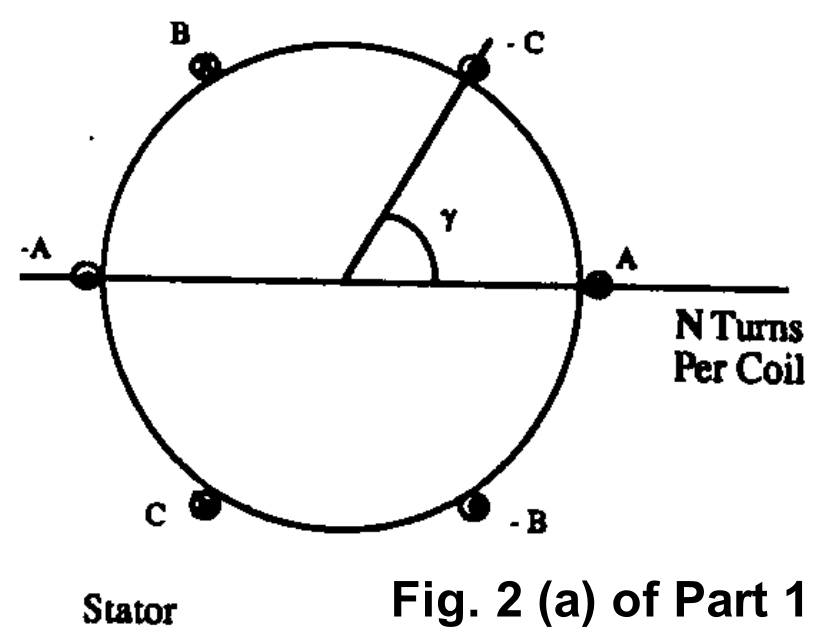

+: current going into the page

-: current going out of the page 

## Space Harmonics (Two-Pole Full-Pitch Concentrated Winding)

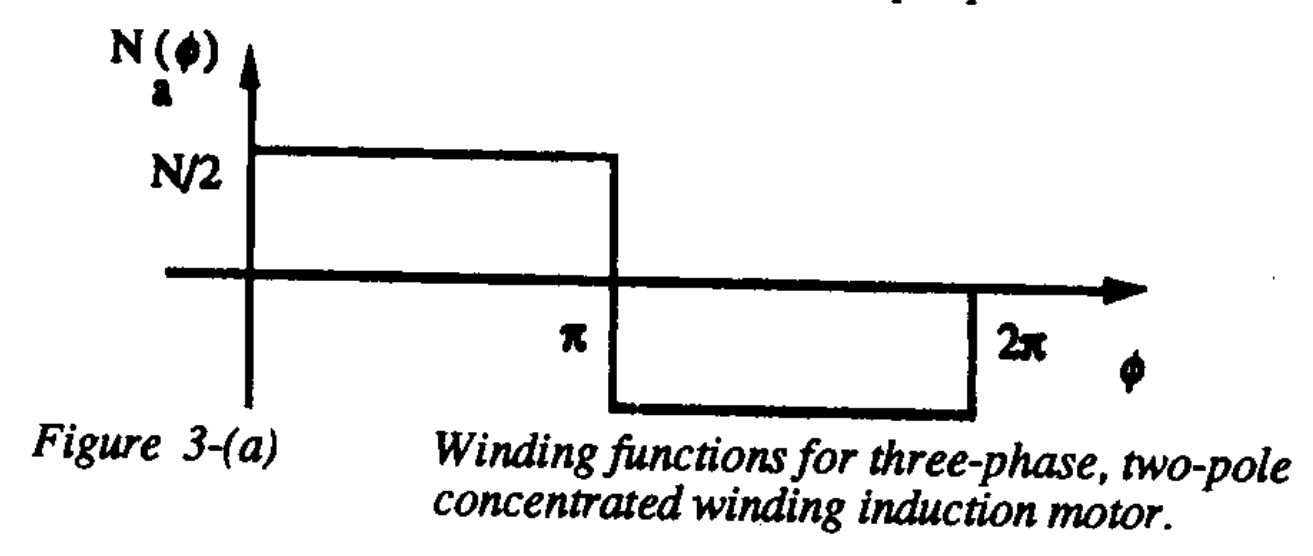

### Numeric Approach 

#### Represent Winding Function Numerically

N_TOTAL = 1;
numOfPoints = 1e3;
T = 2*pi;
phi = linspace(0,T,numOfPoints);

NA = zeros(1,numOfPoints);
% NB = zeros(1,numOfPoints);
% NC = zeros(1,numOfPoints);

NA(phi <= T/2) = N_TOTAL/2;
NA(phi > T/2)  = -N_TOTAL/2; 

#### Find Fourier Series Coefficients

% harmonics order 
numOfHarmonics = 7;
n = 1:numOfHarmonics;

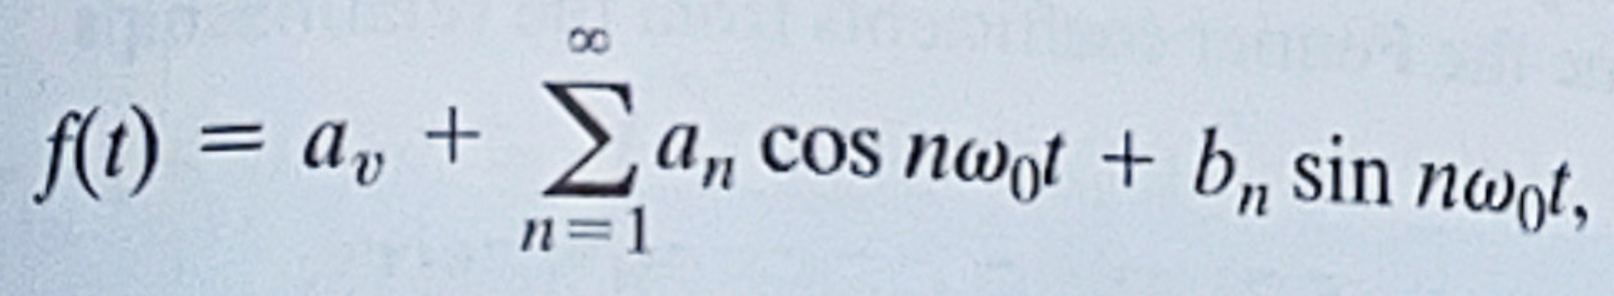

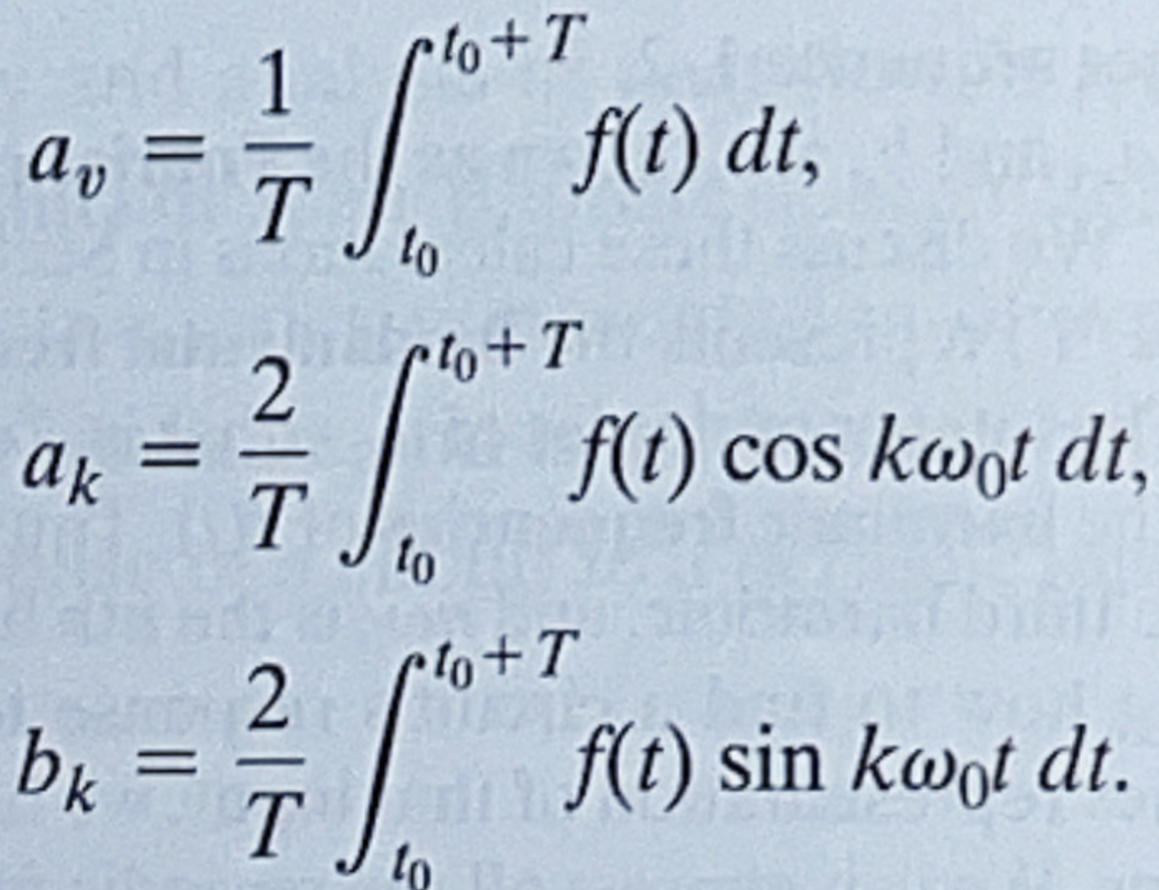

[NA_a0,NA_an,NA_bn] = compute_harmonics_amplitude(NA,phi,n)

NA_a0 = 0

NA_an = 1.0e-15 *

    0.0666   -0.0119    0.0764    0.0260    0.0717    0.0125    0.1306


NA_bn =     0.6360   -0.0000    0.2120   -0.0000    0.1272   -0.0000    0.0909


#### Reconstruct Winding Function from Fourier Series Coefficients

% Preallocate space for Fourier reconstruction
NA_fourier = zeros(1, numOfPoints);  

% Add each harmonic order one by one
for k = 1:length(n)
    NA_fourier = NA_fourier + NA_an(k) * cos(n(k) * phi) + NA_bn(k) * sin(n(k) * phi);
    if k == n(end)
        NA_fourier = NA_fourier + NA_a0;
    end
end

### Symbolic Approach (Paper)

% Use the expression in the paper 
syms theta alpha

digits(4)
tolerance = 1e-7;  % Define your tolerance level

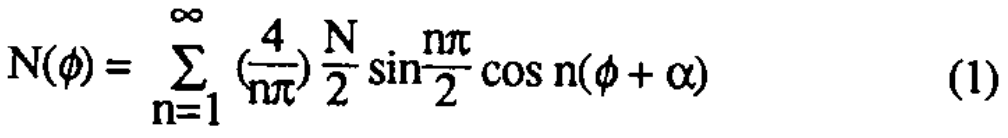

#### Find Fourier Series Coefficients

Note that only sin terms exist. **Is this so-called odd harmonics?**

NA_bn_sym = 4./(n*pi) * N_TOTAL/2 .* sin(n*pi/2);

#### Reconstruct Winding Function from Fourier Series Coefficients

**Two results match only when alpha = -pi/2; otherwise, there will be a phase shift in the result using symbolic approach.**

% sift out minuscule term
NA_bn_sym = subs(NA_bn_sym, theta+alpha, 0);
NA_bn_sym(double(abs(NA_bn_sym)) <= tolerance) = 0;

NA_fourier_sym = vpa( sum( NA_bn_sym .* cos(n.*(theta+alpha)) ) )

$$NA\_fourier\_sym = 0.6366\,\cos\left(\alpha +\theta \right)-0.09095\,\cos\left(7.0\,\alpha +7.0\,\theta \right)-0.2122\,\cos\left(3.0\,\alpha +3.0\,\theta \right)+0.1273\,\cos\left(5.0\,\alpha +5.0\,\theta \right)$$

% NA_fourier_sym = vpa( sum( NA_bn_sym .* sin(n.*(theta+alpha)) ) )

#### Plot Results All-in-One 

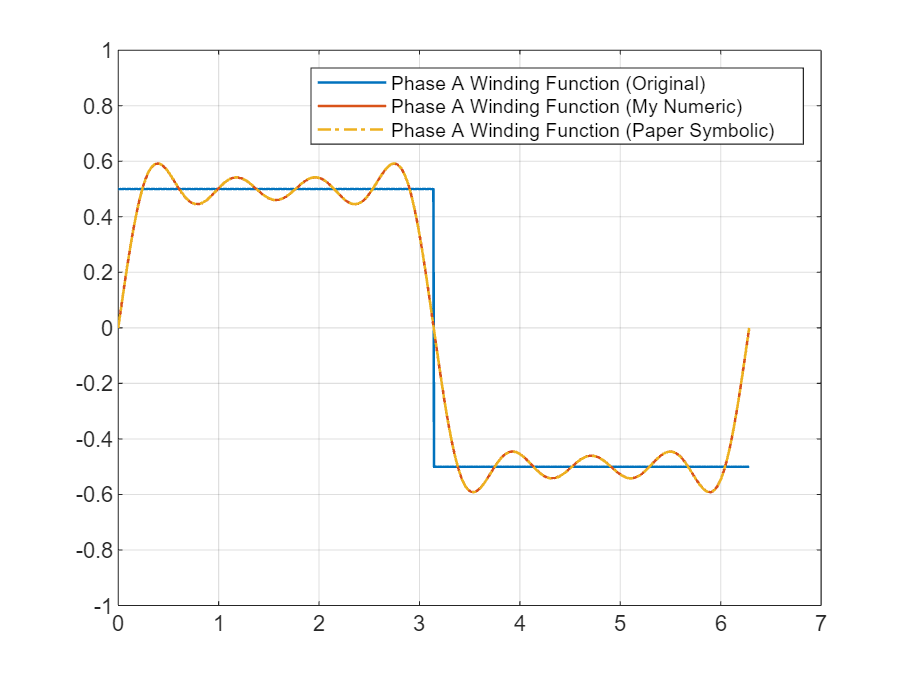

figure

plot(phi,NA, ...
    "LineWidth",1.2, ...
    "DisplayName","Phase A Winding Function (Original)")

hold on 

plot(phi,NA_fourier, ...
    "LineWidth",1.2, ...
    "DisplayName","Phase A Winding Function (My Numeric)")

% alpha has to be -pi/2 
fplot(subs(NA_fourier_sym, alpha, -pi/2), [0 T], ...
    "LineWidth",1.2, ...
    "LineStyle","-.", ...
    "DisplayName","Phase A Winding Function (Paper Symbolic)")

ylim([-1 1])
grid on 
legend 
hold off 

function [a0,an,bn] = compute_harmonics_amplitude(expr,wt,orderOfHarmonics)
    
    a0 = mean(expr);
    
    % Initialization 
    an = zeros(size(orderOfHarmonics));
    bn = zeros(size(orderOfHarmonics));
    
    for n = 1:length(orderOfHarmonics)
        % Amplitude of even harmonics (cos terms)
        an(n) = 2*mean(expr.*cos(n*wt));
    
        % Amplitude of odd harmonics (sin terms) 
        bn(n) = 2*mean(expr.*sin(n*wt));
    end
end 

## Time Harmonics (Six-Step Current)

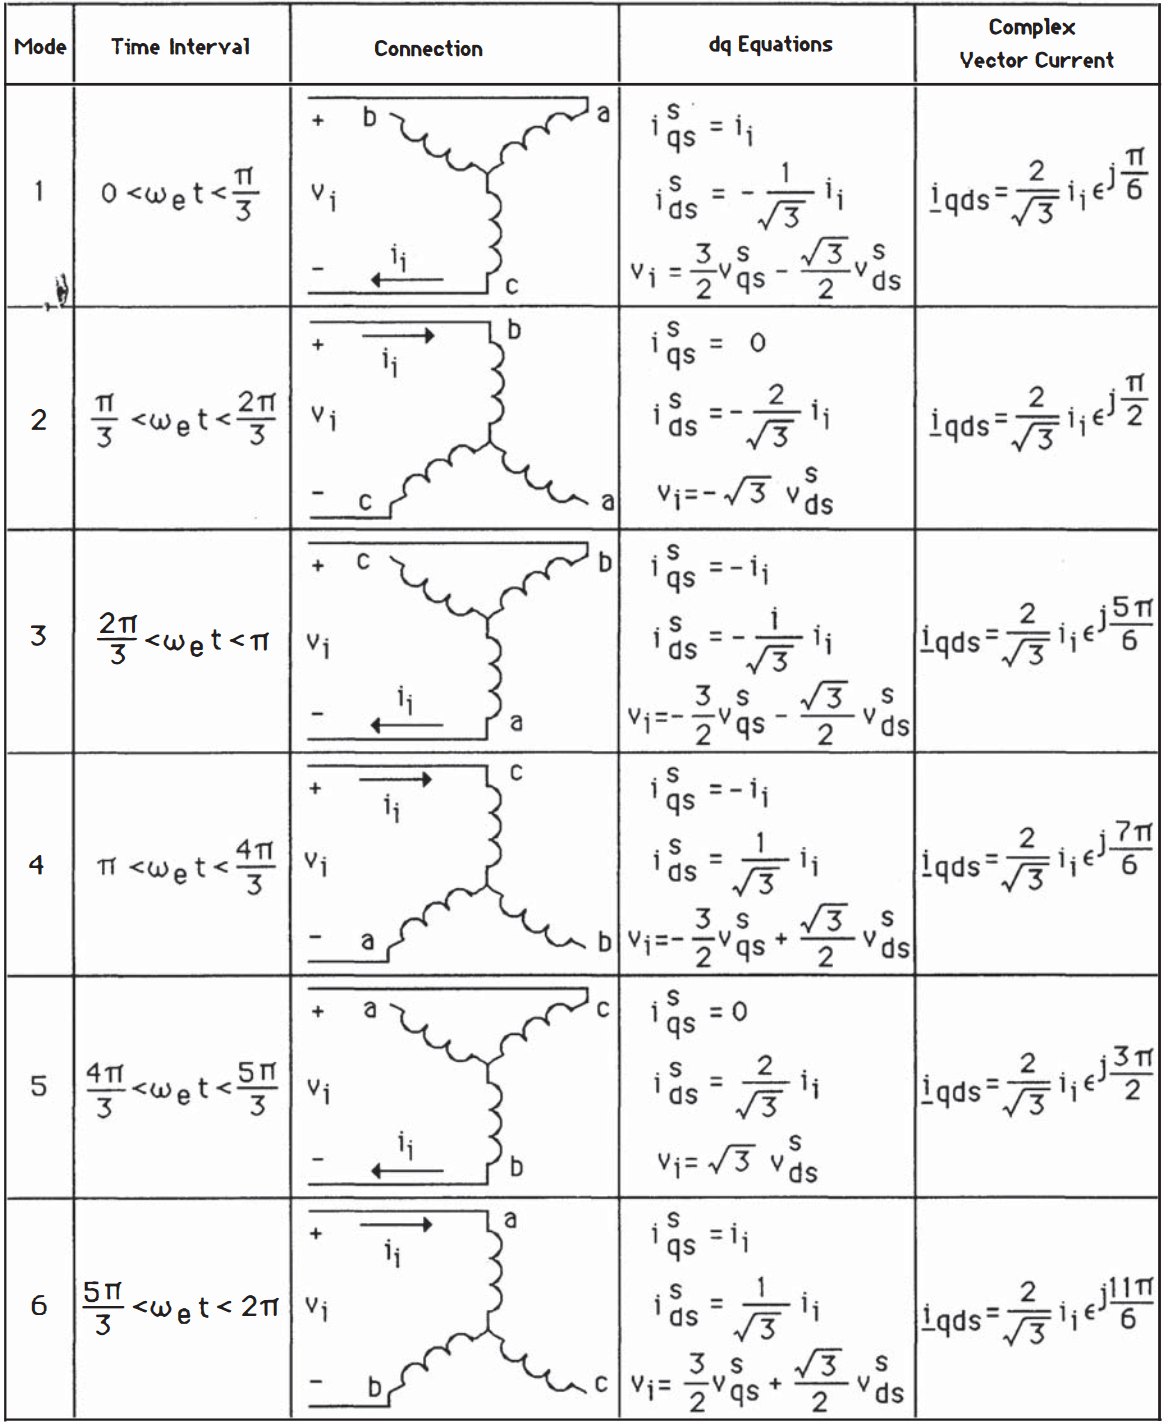

Fig. 3.5 (Vector Control and Dynamics of AC Drives, pg. 117) 

### Numeric Approach

#### Represent Phase A Current Waveform Numerically 

m = 1:numOfHarmonics;

wt = linspace(0, T, numOfPoints);

iA(mod(wt, 2*pi) >= 0 & mod(wt, 2*pi) < pi/3) = 1/2;
iA(mod(wt, 2*pi) >= pi/3 & mod(wt, 2*pi) < 2*pi/3) = -1/2;
iA(mod(wt, 2*pi) >= 2*pi/3 & mod(wt, 2*pi) < pi) = -1;
iA(mod(wt, 2*pi) >= pi & mod(wt, 2*pi) < 4*pi/3) = -1/2;
iA(mod(wt, 2*pi) >= 4*pi/3 & mod(wt, 2*pi) < 5*pi/3) = 1/2;
iA(mod(wt, 2*pi) >= 5*pi/3 & mod(wt, 2*pi) <= 2*pi) = 1;

#### Find Fourier Series Coefficients

Note that both iA_an and iA_bn exist. **However, in the paper it is stated that "Since the current waveforms are symmetric, it is clear that even harmonics again can not exist.?**

[iA_a0,iA_an,iA_bn] = compute_harmonics_amplitude(iA,wt,m)

iA_a0 = 5.0000e-04

iA_an =     0.8264    0.0003    0.0010    0.0002   -0.1650    0.0010    0.1183


iA_bn =    -0.4783    0.0013    0.0000   -0.0013   -0.0941    0.0000   -0.0694


% this time both even and odd harmonics exist 

#### Reconstruct Current Waveform Numerically from Fourier Series Coefficients

% Preallocate space for Fourier reconstruction
iA_fourier = zeros(1, numOfPoints); 

% Add each harmonic order one by one
for k = 1:length(m)
    iA_fourier = iA_fourier + iA_an(k) * cos(n(k) * wt) + iA_bn(k) * sin(n(k) * wt);
    if k == m(end)
        iA_fourier = iA_fourier + iA_a0;
    end
end


#### *Reconstruct Current Waveform Symbolically from Fourier Series Coefficients 

iA_an(double(abs(iA_an)) <= tolerance) = 0;
iA_bn(double(abs(iA_bn)) <= tolerance) = 0;

syms delta
iA_fourier_sym = vpa( iA_a0 + sum(iA_an .* cos(m * (theta+delta)) + iA_bn .* sin(m * (theta+delta))) )

$$iA\_fourier\_sym = 0.001\,\cos\left(3.0\,\delta +3.0\,\theta \right)-0.0941\,\sin\left(5.0\,\delta +5.0\,\theta \right)+0.001\,\cos\left(6.0\,\delta +6.0\,\theta \right)+0.1183\,\cos\left(7.0\,\delta +7.0\,\theta \right)-0.06944\,\sin\left(7.0\,\delta +7.0\,\theta \right)+0.8264\,\cos\left(\delta +\theta \right)-0.4783\,\sin\left(\delta +\theta \right)+0.0002541\,\cos\left(2.0\,\delta +2.0\,\theta \right)+0.0002418\,\cos\left(4.0\,\delta +4.0\,\theta \right)+0.001301\,\sin\left(2.0\,\delta +2.0\,\theta \right)-0.001294\,\sin\left(4.0\,\delta +4.0\,\theta \right)-0.165\,\cos\left(5.0\,\delta +5.0\,\theta \right)+0.0005$$


% Rewrite iA_fourier_sym into sin terms only 
% iA_fourier_sym = rewrite(iA_fourier_sym,"sin") % introduce sin^2 terms
% which are unwanted 

% iA_fourier_sym_sin = rewrite( subs(iA_fourier_sym, delta, delta+pi/2), "sin" )

## Symbolic Approach (Paper)

#### Find Fourier Series Coefficients

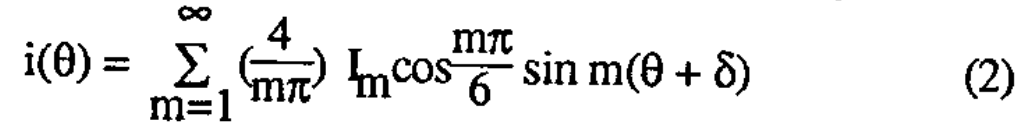

**It is unclear what current waveforms the paper adopts. Do we have a generic (default) six-step waveform?**

"Since current waveforms are symmetric, it is clear that even harmonics again can not exist." **But why am I getting both even and odd harmonics?**

syms delta I_m
i_bn_sym = 4./(m*pi) * I_m .* cos(m*pi/6);

i_bn_sym = subs(i_bn_sym, I_m, 1);               % could be arbitrary as we only care about the shape of waveform
i_bn_sym(double(abs(i_bn_sym)) <= tolerance) = 0;

i_fourier_sym = vpa( sum( i_bn_sym .* sin(m.*(theta+delta)) ) )

$$i\_fourier\_sym = 1.103\,\sin\left(\delta +\theta \right)-0.2122\,\sin\left(6.0\,\delta +6.0\,\theta \right)-0.1575\,\sin\left(7.0\,\delta +7.0\,\theta \right)-0.2205\,\sin\left(5.0\,\delta +5.0\,\theta \right)+0.3183\,\sin\left(2.0\,\delta +2.0\,\theta \right)-0.1592\,\sin\left(4.0\,\delta +4.0\,\theta \right)$$

#### Plot Results All-in-One 

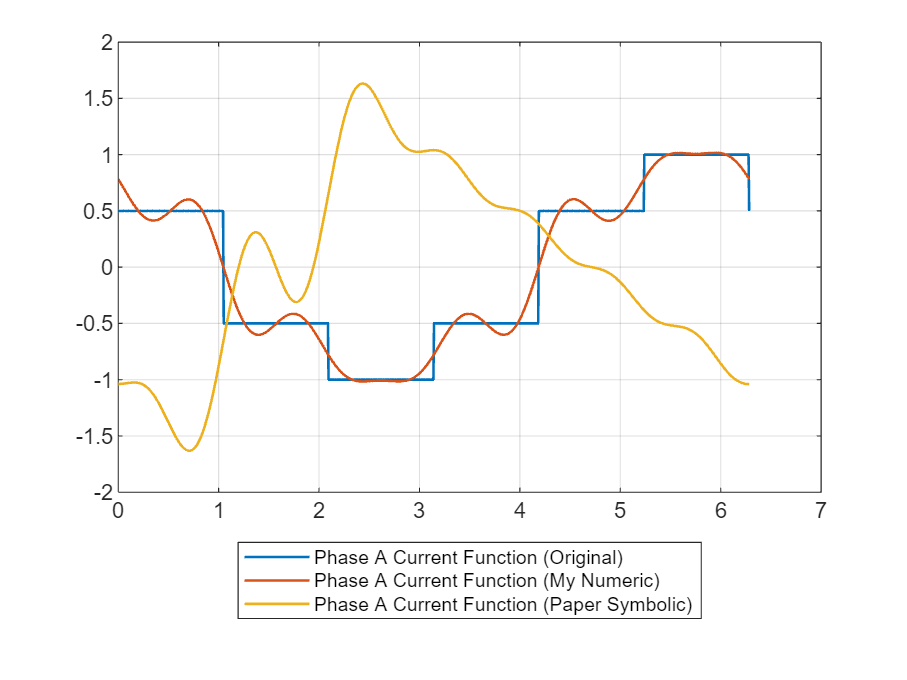

figure

plot(wt,iA, ...
    "LineWidth",1.2, ...
    "DisplayName","Phase A Current Function (Original)")

hold on 

plot(wt,iA_fourier, ...
    "LineWidth",1.2, ...
    "DisplayName","Phase A Current Function (My Numeric)")

hold on 

% fplot(subs(iA_fourier_sym, delta, 0), [0 T], ...
%     "LineWidth",1.2, ...
%     "DisplayName","Phase A Current Function (My Symbolic Fourier)")

fplot(subs(i_fourier_sym, delta, -pi/2), [0 T], ...
    "LineWidth",1.2, ...
    "DisplayName","Phase A Current Function (Paper Symbolic)")

ylim([-2 2])
grid on 
legend("Location","southoutside") 
hold off 

## My Harmonics Table

% open ECEN611_HW2_Shuxuan_SixStep.mlx